clc; clear all; close all;
    % Make Pipeline object to manage streaming
    pipe = realsense.pipeline();
    
    % Start streaming on an arbitrary camera with default settings
    profile = pipe.start();


    %% Acquire device parameters 
    % Get streaming device's name
    dev = profile.get_device();  

    % Access Depth Sensor
    depth_sensor = dev.first('depth_sensor');

    % Find the mapping from 1 depth unit to meters, i.e. 1 depth unit =
    % depth_scaling meters.
    depth_scaling = depth_sensor.get_depth_scale();

    % Extract the depth stream
    depth_stream = profile.get_stream(realsense.stream.depth).as('video_stream_profile');
    
    % Get the intrinsics
    depth_intrinsics = depth_stream.get_intrinsics();

    %% Align the frames and then get the frames
    % Get frames. We discard the first couple to allow
    % the camera time to settle
    for i = 1:5
        fs = pipe.wait_for_frames();
    end
    
    % Alignment is necessary as the depth cameras and RGB cameras are
    % physically separated. So, the same (x,y,z) in real world maps to
    % different (u,v) in the depth image and the color images. To build a
    % point cloud we only need depth image, but if we want the color the
    % cloud then we'll need the other image.

    % Since the two images are of different sizes, we can either align the
    % depth to color image, or the color to depth.
    % Change the argument to realsense.stream.color to align to the color
    % image.
    align_to_depth = realsense.align(realsense.stream.depth);
    fs = align_to_depth.process(fs);
    
    % Stop streaming
    pipe.stop();

    % Extract the depth frame
    depth = fs.get_depth_frame();
    depth_data = double(depth.get_data());
    depth_frame = permute(reshape(depth_data',[ depth.get_width(),depth.get_height()]),[2 1]);

    % Extract the color frame
    color = fs.get_color_frame();    
    color_data = color.get_data();
    color_frame = permute(reshape(color_data',[3,color.get_width(),color.get_height()]),[3 2 1]);

    %% Create a point cloud using MATLAB library
    % Create a MATLAB intrinsics object
    intrinsics = cameraIntrinsics([depth_intrinsics.fx,depth_intrinsics.fy],[depth_intrinsics.ppx,depth_intrinsics.ppy],size(depth_frame));
    
    % Create a point cloud
    ptCloud = pcfromdepth(depth_frame,1/depth_scaling,intrinsics,ColorImage=color_frame)

ptCloud =   pointCloud with properties:

     Location: [480×640×3 single]
        Count: 307200
      XLimits: [-0.3412 0.3045]
      YLimits: [-0.2844 0.2728]
      ZLimits: [0 0.5673]
        Color: [480×640×3 uint8]
       Normal: []
    Intensity: []


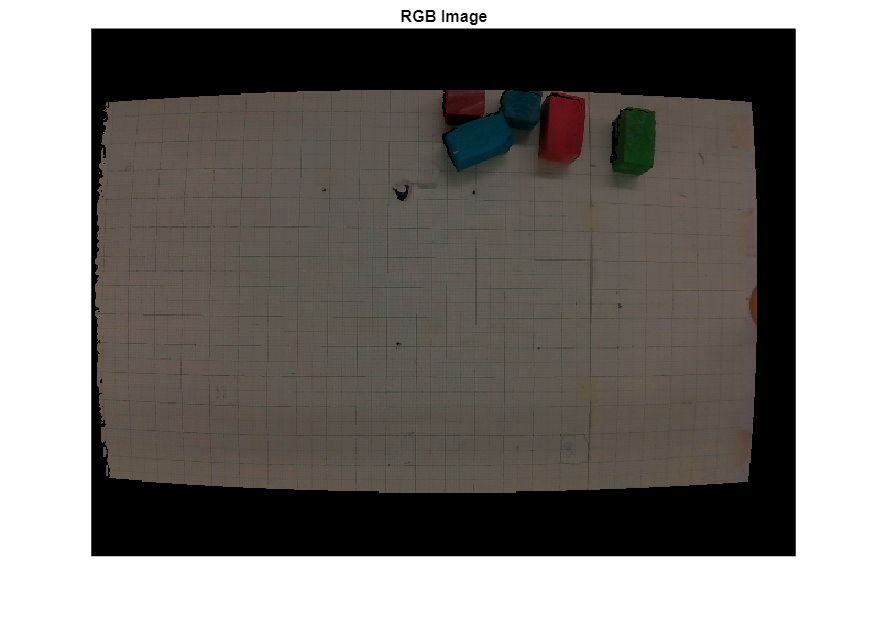

    
rgb = (ptCloud.Color);

imshow(rgb, [])
title("RGB Image")

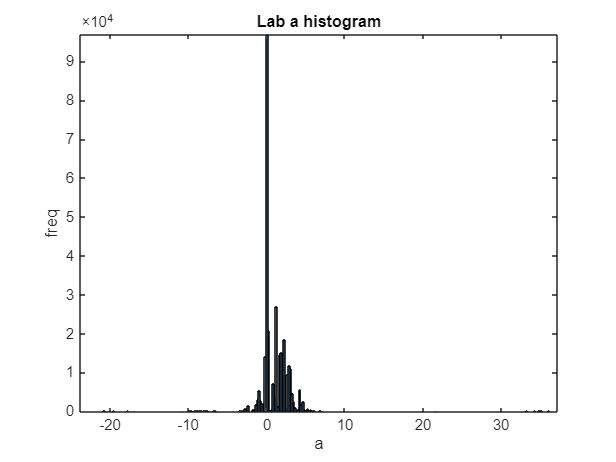

Lab = rgb2lab(rgb);
figure;
histogram(Lab(:,:,2)); %a
title("Lab a histogram")
xlabel("a");
ylabel("freq");
axis tight;

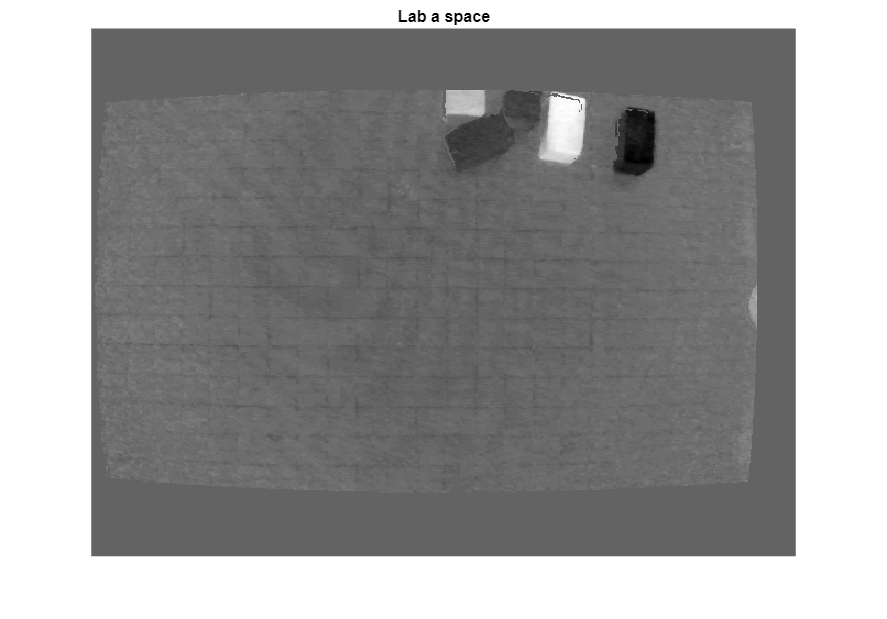


imshow(Lab(:,:,2),[]);
title("Lab a space")

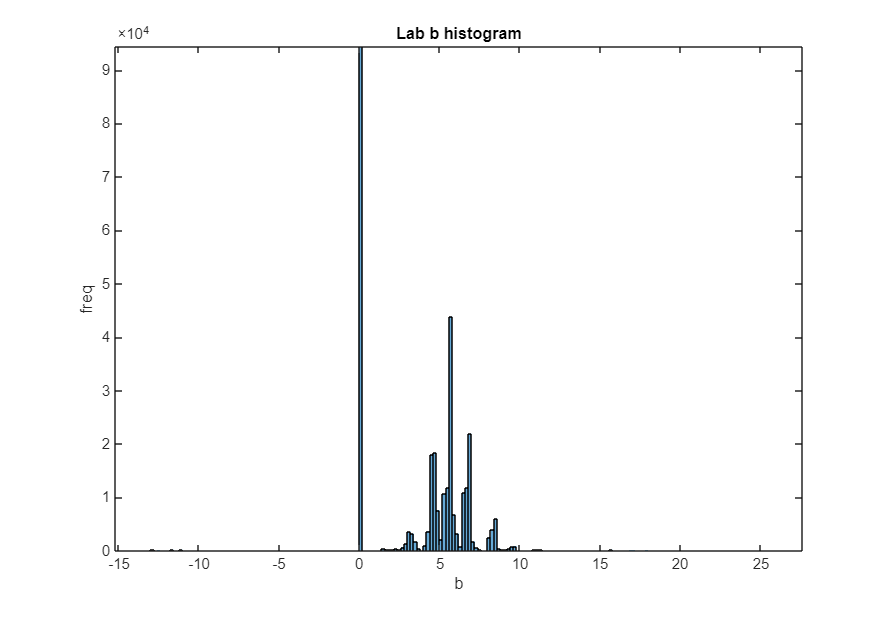


histogram(Lab(:,:,3)); %b
title("Lab b histogram")
xlabel("b");
ylabel("freq");
axis tight;

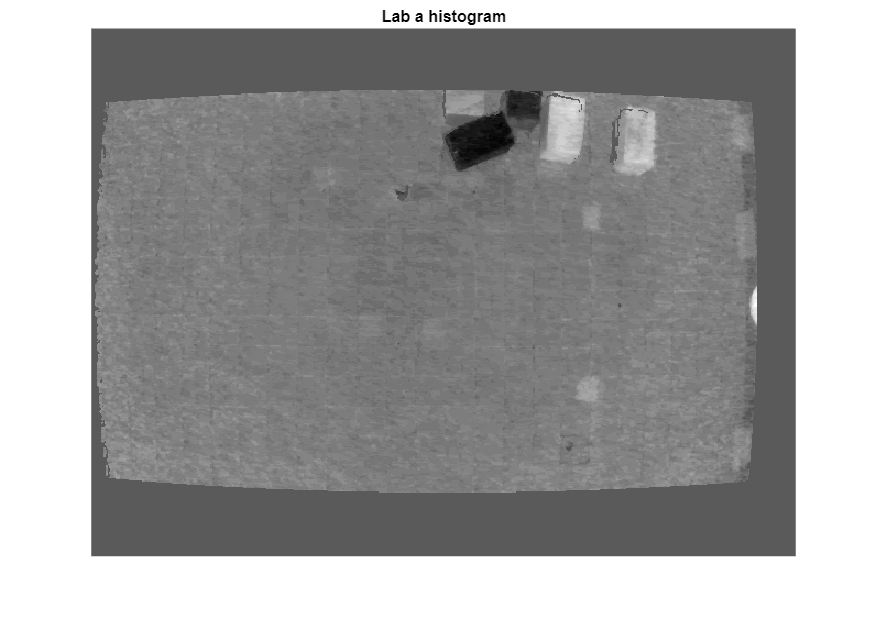


imshow(Lab(:,:,3), []);
title("Lab a histogram")

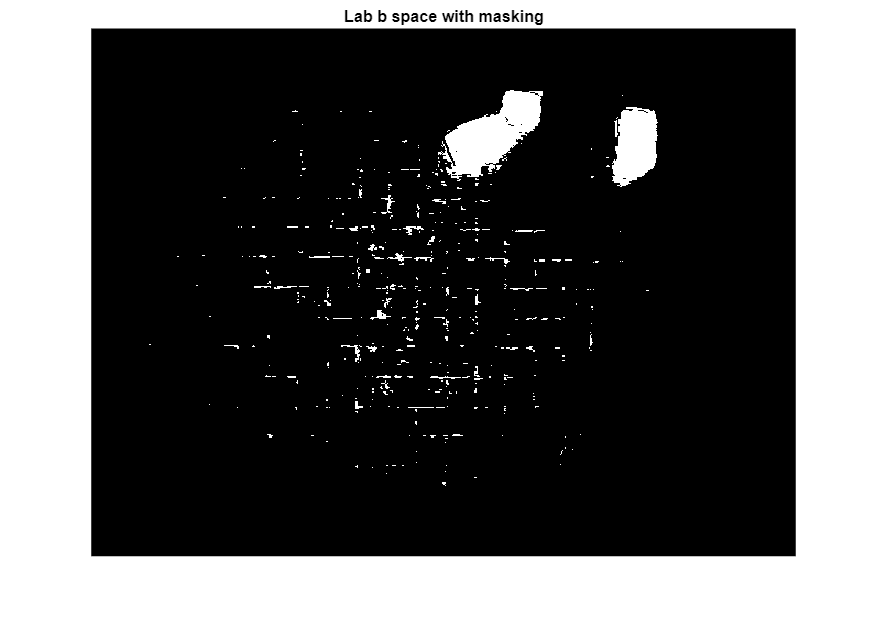


lightMask = (Lab(:,:,2) < -2);
imshow(lightMask, []);
title("Lab b space with masking")



% bwMask = bwareaopen(bwMask, 100);
% bwMask = imfill(bw2, 'holes');
% 
% X = ptCloud.Location(:,:,1);
% Y = ptCloud.Location(:,:,2);
% Z = ptCloud.Location(:,:,3);
% 
% lightpoints = [X(), Y(), Z()];


% pcshow(pointCloud(lightpoints), "VerticalAxisDir","Down");

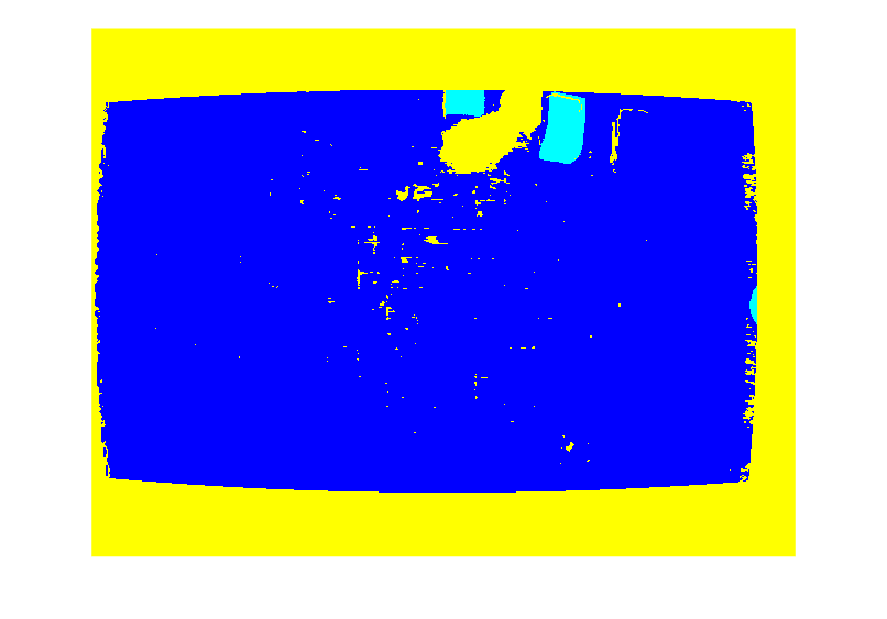

pixel_labels = segment_cluster(rgb, 3);
% overlay = labeloverlay(rgb, pixel_labels);
display = label2rgb(pixel_labels, 'jet');
imshow(display);

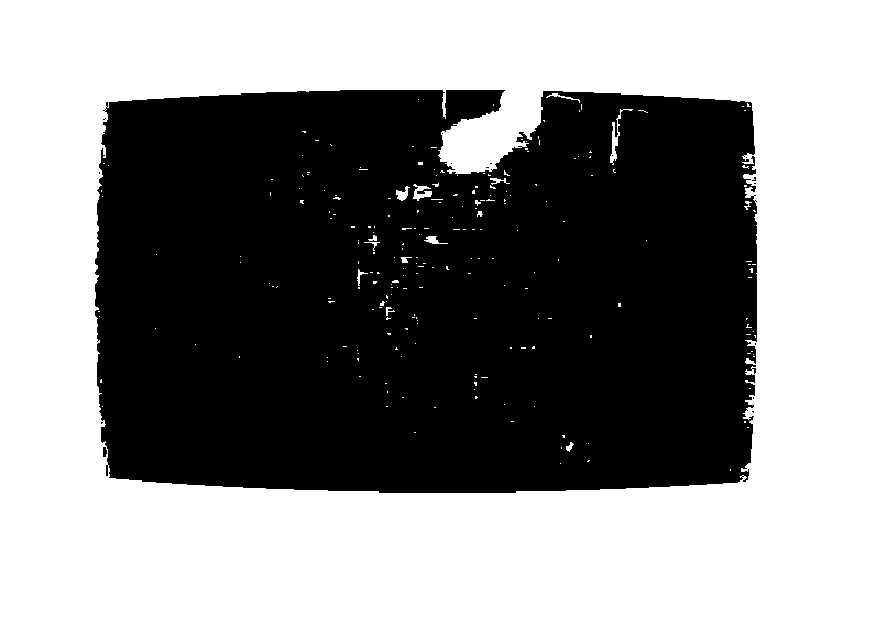


mask = (pixel_labels == 3);

X = ptCloud.Location(:,:,1);
Y = ptCloud.Location(:,:,2);
Z = ptCloud.Location(:,:,3);

points_xyz = [ ...
    X(mask), ...
    Y(mask), ...
    Z(mask) ...
];



imshow(mask, []);

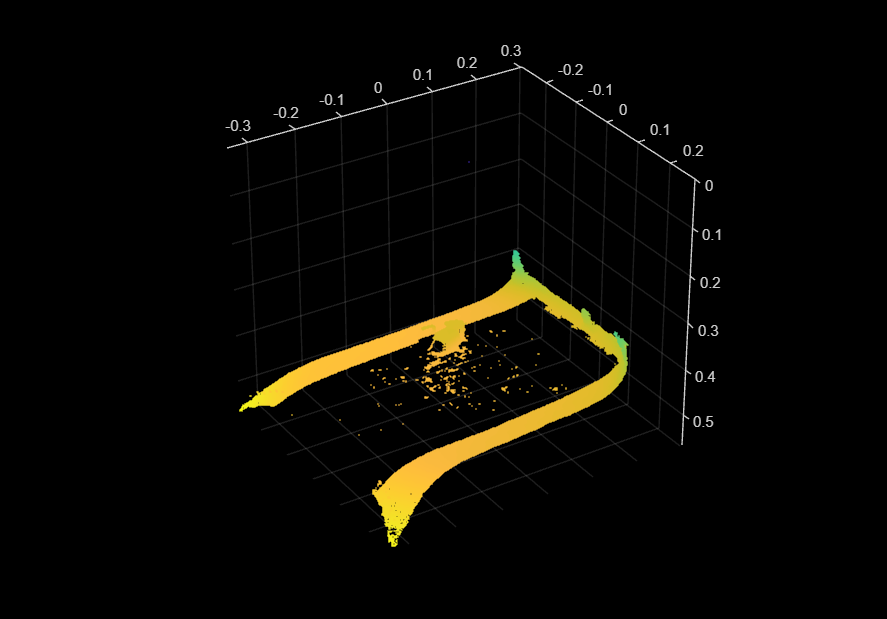


% 
pc = pointCloud(points_xyz);
pcshow(pc, "VerticalAxisDir","Down");

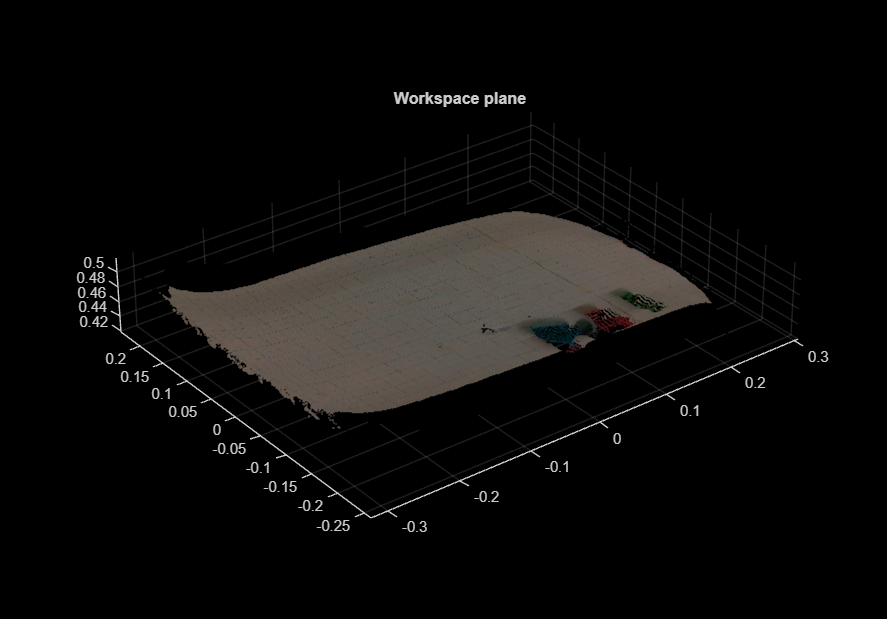

maxDistance = 0.025; % 0.3 cm
referenceVector = [0, 0, 1]; % z axis
maxAngularDistance = 5; % degrees

[model1,inlierIndices,outlierIndices] = pcfitplane(ptCloud,...
            maxDistance,referenceVector,maxAngularDistance);

plane1 = select(ptCloud,inlierIndices);
pcshow(plane1)
title("Workspace plane")

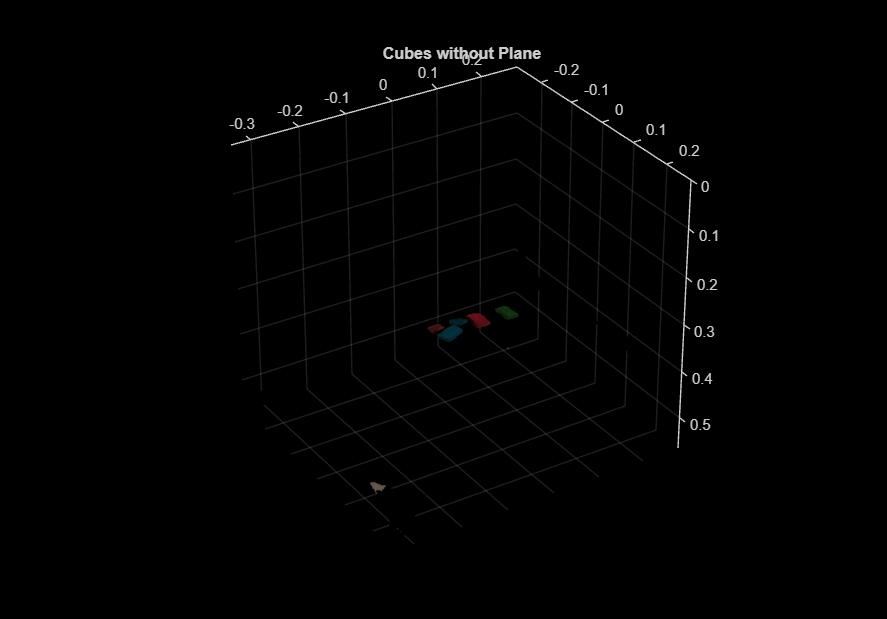


remainPtCloud = select(ptCloud,outlierIndices);

pcshow(remainPtCloud, "VerticalAxisDir","Down")
title("Cubes without Plane")


rgb_cubes = remainPtCloud.Color;

imshow(rgb_cubes, []);

% 
% planeModel = pcfitplane(ptCloud, 0.01);
% inlierIdx = planeModel.InlierIndices;
% 
% nonPlaneMask = true(m*n,1);
% nonPlaneMask(inlierIdx) = false;
% nonPlaneMask = reshape(nonPlaneMask, m, n);

% validMask = validMask & nonPlaneMask;











% X = ptCloud.Location(:,:,1);
% Y = ptCloud.Location(:,:,2);
% Z = ptCloud.Location(:,:,3);
% 
% validMask = Z > 0 & ~isnan(Z); % getting valid depth values
% 
% rgb_double = im2double(rgb);
% 
% [m,n,~] = size(rgb_double); % ignore channels
% pixels = reshape(rgb_double, m*n, 3);
% 
% % getting rgb values corresponding to correct Z
% valid_pixels = pixels(validMask(:), :);
% 
% [idx_valid, C] = kmeans(valid_pixels, 7, 'Replicates', 3); % replicate = parallelize
% 
% pixel_labels(validMask(:)) = idx_valid;
% 
% pixel_labels = reshape(pixel_labels, m, n);
% 
% 
% 
% display = label2rgb(pixel_labels, 'jet');
% imshow(display);
% title("RGB Clustering")
% 
% 
% mask = (pixel_labels == greenCluster);
% 
% points_xyz = [ ...
%     X(mask), ...
%     Y(mask), ...
%     Z(mask) ...
% ];
% pc = pointCloud(points_xyz);
% pcshow(pc, "VerticalAxisDir","Down");
% title("RGB Masked Point Cloud")



% hsv_img = rgb2hsv(rgb_double);
% pixels = reshape(hsv_img, m*n, 3);
% valid_pixels = pixels(validMask(:), 1:2);  % Use Hue + Saturation only
% 
% % [idx_valid, C] = kmeans(valid_pixels, 4, 'Replicates', 3); % replicate = parallelize
% pixel_labels = segment_cluster(image_rgb, numColors, debug)
% 
% pixel_labels = zeros(m*n,1);
% pixel_labels(validMask(:)) = idx_valid;
% 
% pixel_labels = reshape(pixel_labels, m, n);
% 
% display = label2rgb(pixel_labels, 'jet');
% imshow(display);
% title("HSV Clustering")

